# **Lab7 : Newton-Kleinman**

**Data trecuta **am vorbit despre **Metoda Vectorilor Schur**. Am vazut ca este o metoda usurica de inteles si precisa, insa ea are o problema mare: este nasol din punct de vedere numeric $O(9n^{3})$

Cum putem afla acum *cu aproximatie* solutia Ecuatiei Riccati, fara sa ne omoare numeric? Folosind un algoritm iterativ, si anume** Newton-Kleinman **

Facand presupunerea ca $\left\lbrace \begin{array}{l}
\left(A,B\right)\;\mathrm{stabilizabil}\\
\left(\overline{Q_n } ,A\right)\;\mathrm{detectabil}
\end{array}\right.,\mathrm{unde}\;\overline{Q_n } \;\mathrm{este}\;\mathrm{chol}\left(Q_n \right)$, pentru a minimiza $J(x_{f0},u(t))$, se va rezolva EMAR/CARE post-avarie:

$A^{T}_{f}X_{f}+X_{f}A_{f}-X_{f}B_{f}R_{n}^{-1}B^{T}_{f}X_{f}+Q_{n}=0$. Folosind $X_{f}$, obtinem legea de comanda post-avarie $u_{f}(t)=-K_{f}x(t), K_{f}=R_{n}^{-1}B_{f}^{T}X_{f}$ si noul sistem in bucla inchisa $\hat{M_f}:\dot{x}=\hat{A_f}x(t), \hat{A_f}=A_{f}-B_{f}K_{f}$

## Acum intram in algoritm propriu-zis:

**Pe scurt:** din EMAR neliniar $\approx$Lyapunov liniar

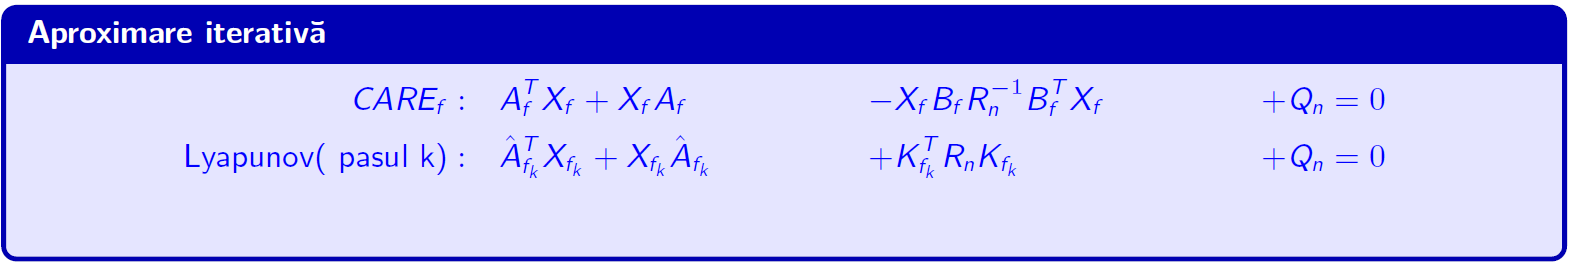

Pentru a garanta convergenta acestui algoritm $(lim_{k->\infty}X_{f_{k}})$, adica existenta **initializarii stabilizante**, se folosesc doua abordari:

- Initializare **Kleinman**

- Initializare **Bass-Armstong**

### Algoritm generic Newton-Kleinman:

- Se alege $K_{f_{1}}$ astfel incat $\hat{A_f}=A_{f}-B_{f}K_{f_{1}}$ sa fie stabil, adica $\Lambda(\hat{A_{f_1}})\in \mathbb{C}^{-}$

- Se vor face urmatorii pasi pana cand $||X_{f_{k}}-X_{Ricc}||_{F}<toleranta$, toleranta impusa de noi:

- Se determina $X_{f_{k}}$ ca unica solutie pozitiv-semidefinita a ecuatiei **Lyapunov** $\hat{A_{f_{k}}}^{T}X_{f_{k}}+X_{f_{k}}\hat{A_{f_{k}}}+K_{f_{k}}^{T}R_{n}K_{f_{k}}+Q_{n}=0$

- Se actualizeaza pasul urmator (k+1): $K_{f_{k+1}}=R_{n}^{-1}B_{f}^{T}X_{f_k}}$ si $\hat{A}_{f_{k+1}}=A_{f}-B_{f}K_{f_{k+1}}$

Daca sistemul $\dot{x}=A_{f}x(t)+B_{f}u_{f}(t)$, se poate asigura un pas initial stabilizant prin:

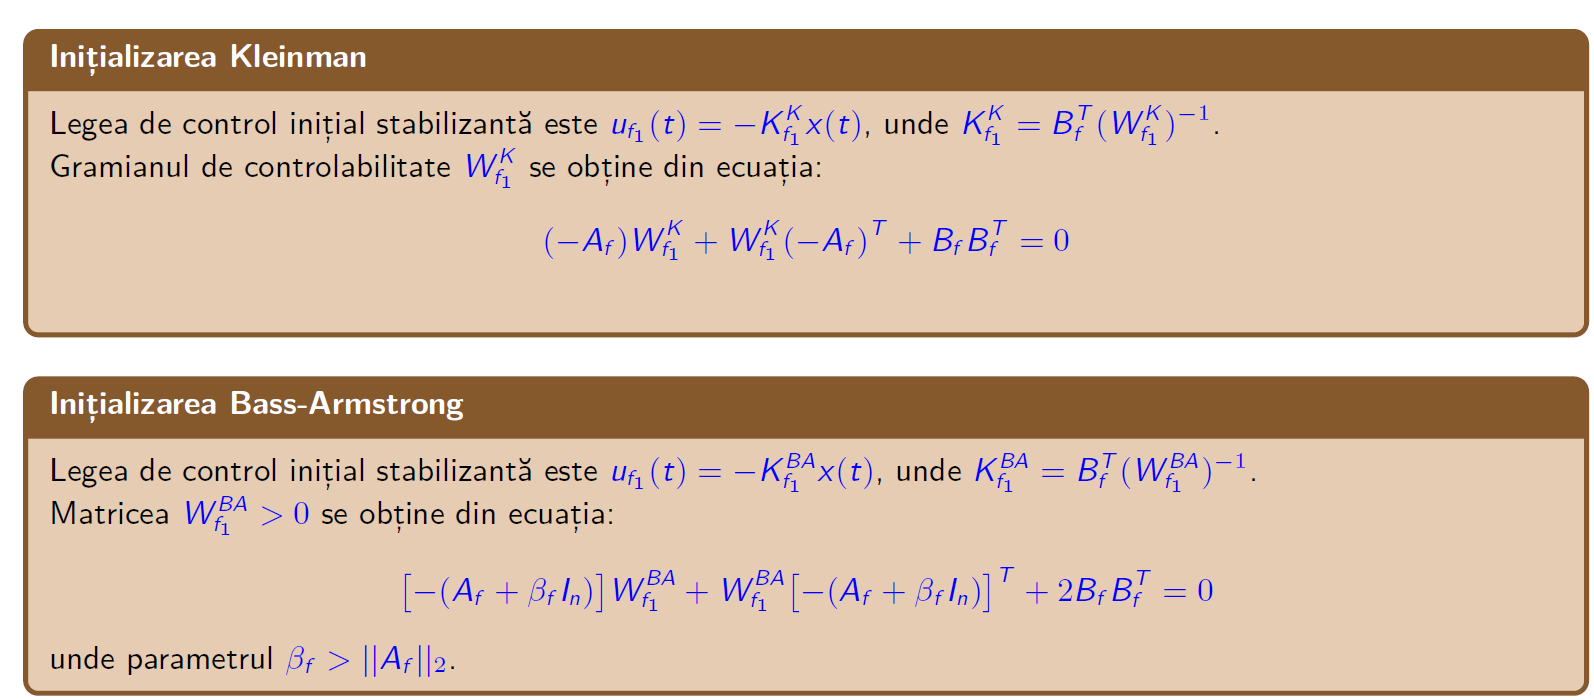

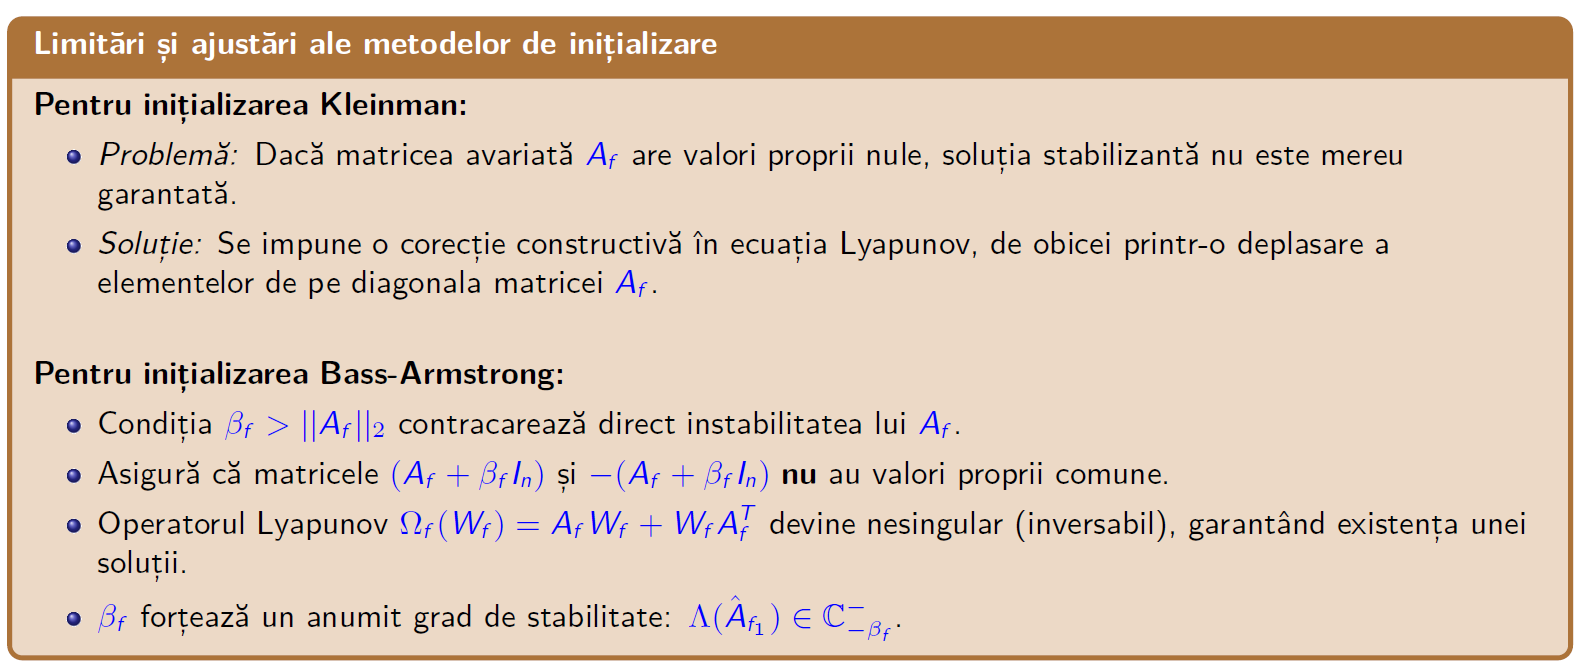

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

Iau defectele aici

Af_lon = A_lon * 0.95

Af_lon =    -0.9310    0.0000   -0.0006   -0.0152
    0.9500         0         0         0
   -2.0900   -9.3100   -0.0314    0.0703
   73.1500   -0.7315   -0.2185   -0.6365



Bf_lon = B_lon * 0.7

Bf_lon =    -1.6800    0.2030
         0         0
    0.1260    6.8600
   -4.5500         0


Sistem controlabil

tzero(Af_lon,Bf_lon,[],[])


ans =

  0×1 empty double column vector



Sistem observabil

tzero(Af_lon, [], C_lon, [])


ans =

  0×1 empty double column vector



Aleg Q si R

Q = diag([10 100 5 5])

Q =     10     0     0     0
     0   100     0     0
     0     0     5     0
     0     0     0     5


R = diag([10 10])

R =     10     0
     0    10


[Xn,Kn] = icare(A_lon,B_lon,Q,R)

Xn = 1.0e+03 *

    0.0210    0.1542   -0.0003   -0.0003
    0.1542    4.1981   -0.0034   -0.0496
   -0.0003   -0.0034    0.0007    0.0000
   -0.0003   -0.0496    0.0000    0.0010


Kn =    -4.8678   -4.8135    0.0704   -0.6024
    0.2680    1.1012    0.6989    0.0314


Acum face Newton-Kleinman

Iau sistemul in bucla inchisa

Vad ca e stabil

eig(Af_lon - Bf_lon * Kn)

ans =   -6.2500 + 7.2047i
  -6.2500 - 7.2047i
  -0.0425 + 0.0000i
  -4.8332 + 0.0000i


X_prev = zeros(4,4)

X_prev =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Kf_pas_k = Kn;

Aici fac vector de erori

err_hist_NK = [];

Aflu Xf si Kf

[Xf, Kf] = icare(Af_lon, Bf_lon, Q, R)

Xf = 1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012


Kf =    -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373


Si de aici Newton ala

for i = 1:1e2
    Afhat = Af_lon - Bf_lon * Kf_pas_k;
    Qhat = Q + Kf_pas_k' * R * Kf_pas_k;


Pun transpus la Afhat pentru a respecta Lyapunov

    X_k = lyap(Afhat', Qhat);

X_NK = 1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012


    if isempty(tzero(Afhat, Bf_lon,[],[]))
    else
        disp('Nu este stabil');

Xi final este:


        return

   1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012



    end


Xf nominal:


Aici fac vectorul ala de erori pentru a-l putea reprezenta grafic

    err = norm(Xf-X_k, 'fro');

   1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012



    err_hist_NK = [err_hist_NK, err];
    Kf_pas_k = eye(2) / R * Bf_lon' * X_k;

Ki final este:


    X_prev = X_k;

   -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373



end
X_NK = X_k

Kf nominal:


Kf_NK = Kf_pas_k;

   -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373



Vad vizual daca e ok

disp('Xi final este:');
disp(X_NK)

disp('Xf nominal:');

Mergeeeeeee


ans = 5.4588e-12

disp(Xf)

disp('Ki final este:');
disp(Kf_NK)


Mergeeeeeee 2


ans = 9.8998e-14

disp('Kf nominal:');
disp(Kf)

Vad la norme

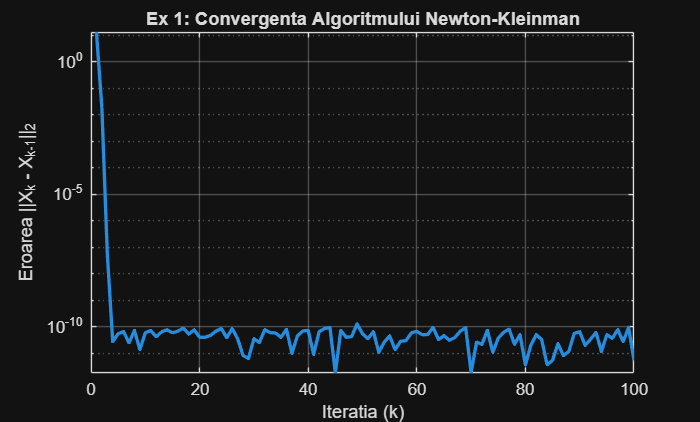

if norm(Xf - X_NK,'fro') < 1e-5
    disp('Mergeeeeeee');
    norm(Xf - X_NK,'fro')
end


if norm(Kf - Kf_NK,'fro') < 1e-5
    disp('Mergeeeeeee 2');
    norm(Kf - Kf_NK,'fro')
end

E =    77.0490         0         0         0
         0    9.8180         0         0
         0         0    0.0264         0
         0         0         0    0.0016


Acum vad grafic

figure;

DeltaAf_BA = 0.7705

semilogy(1:length(err_hist_NK), err_hist_NK, 'LineWidth', 2);
title('Ex 1: Convergenta Algoritmului Newton-Kleinman');

Af_BA =    -0.2095    0.0000   -0.0006   -0.0160
    1.0000    0.7705         0         0
   -2.2000   -9.8000    0.7375    0.0740
   77.0000   -0.7700   -0.2300    0.1005


xlabel('Iteratia (k)');
ylabel('Eroarea ||X_k - X_{k-1}||_{2}');

beta_f = 76.1965

grid on;

## Bass Armstrong

De aici extrag valorile singulare

[~,E,~] = svd(A_lon)

A_BA =   -75.2655   -0.0000    0.0006    0.0152
   -0.9500  -76.1965         0         0
    2.0900    9.3100  -76.1652   -0.0703
  -73.1500    0.7315    0.2185  -75.5600


Acum iau $\Delta A_f$

DeltaAf_BA = max(diag(E)) * 1e-2

Q_BA =     5.7272         0    2.3618   15.2880
         0         0         0         0
    2.3618         0   94.1510   -1.1466
   15.2880         0   -1.1466   41.4050


Asta este o deplasare de valori proprii

Af_BA = A_lon + eye(4) * DeltaAf_BA

W_BA =     0.0381   -0.0002    0.0161    0.0829
   -0.0002    0.0000   -0.0001   -0.0004
    0.0161   -0.0001    0.6185   -0.0134
    0.0829   -0.0004   -0.0134    0.1936


Aici iau acest $\beta_f$

beta_f = norm(Af_lon,2) + 3

Kf_BA = 1.0e+05 *

   -0.0687   -2.0355    0.0020    0.0251
    0.2332    6.7652   -0.0067   -0.0862


Acum pregatesc termenii pentru **Bass-Armstrong** A si Q aia

A_BA = -(Af_lon + beta_f * eye(4))
Q_BA = 2 * (Bf_lon * Bf_lon')

Acum rezolvam Lyapunovu

W_BA = lyap(A_BA, Q_BA)

Asta este solutia stabilizatoare

Kf_BA = Bf_lon' * eye(4) / W_BA

Xf = 1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012


Kf =    -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373


Pregatire pentru NK

X_prev = zeros(4,4);
Kf_pas_k = Kf_BA;
err_hist_BA = [];

Acum alfu Xf si Kf aia

[Xf, Kf] = icare(Af_lon, Bf_lon, Q, R)

Acum NK

for i = 1:1e2
    Afhat = Af_lon - Bf_lon * Kf_pas_k;
    Qhat = Q + Kf_pas_k' * R * Kf_pas_k;

Xf = 1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012


Kf =    -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373


    X_k = lyap(Afhat',Qhat);
    if isempty(tzero(Afhat, Bf_lon,[],[]))

Xi final este:


    else

   1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012



        disp('Nu este stabil');
        tzero(Afhat, Bf_lon,[],[])

Xf nominal:


        return

   1.0e+03 *

    0.0331    0.1719   -0.0005    0.0004
    0.1719    4.5164   -0.0039   -0.0527
   -0.0005   -0.0039    0.0010    0.0000
    0.0004   -0.0527    0.0000    0.0012



    end
    err = norm(Xf - X_k, 'fro');

Ki final este:


    err_hist_BA = [err_hist_BA, err];

   -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373



    Kf_pas_k = eye(2) / R * Bf_lon' * X_k;
    X_prev = X_k;

Kf nominal:


end

   -5.7363   -4.9241    0.0785   -0.5913
    0.3235    0.8292    0.6968    0.0373



X_BA = X_k;
Kf_BA = Kf_pas_k;

Mergeeeeeee


ans = 4.9186e-11

Vad vizual daca e ok

[Xf, Kf] = icare(Af_lon, Bf_lon, Q, R)

disp('Xi final este:');
disp(X_BA)

Mergeeeeeee 2


ans = 6.2953e-14

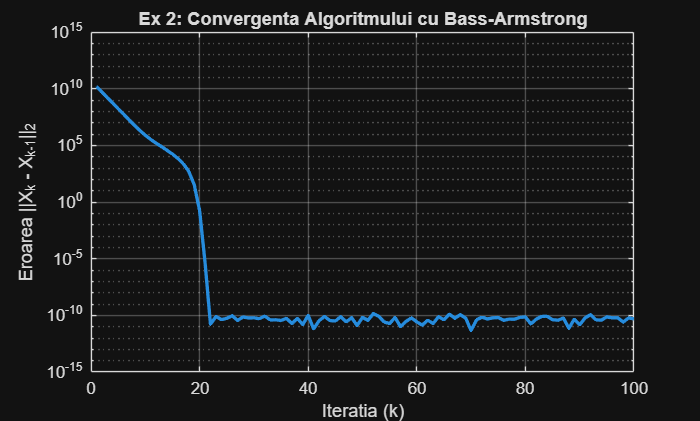


disp('Xf nominal:');
disp(Xf)

disp('Ki final este:');
disp(Kf_BA)

disp('Kf nominal:');

disp(Kf)

Acum ma uit la norme

if norm(Xf - X_BA,'fro') < 1e-5
    disp('Mergeeeeeee');
    norm(Xf - X_BA,'fro')
end

if norm(Kf - Kf_BA,'fro') < 1e-5
    disp('Mergeeeeeee 2');
    norm(Kf - Kf_BA,'fro')
end
clear ans

Acum vad grafic

figure;
semilogy(1:length(err_hist_BA), err_hist_BA, 'LineWidth', 2);
title('Ex 2: Convergenta Algoritmului cu Bass-Armstrong');
xlabel('Iteratia (k)');
ylabel('Eroarea ||X_k - X_{k-1}||_{2}');
grid on;